# Eksamen F2022

Mathias Bruun Houmøller  -  202006837

format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)
% latex(expr)

## Opgave 1 

Mathias Bruun Houmøller  -  202006837

a)

Data indskrives

clear
m_L = 100; %kg
s_L = 0.75; % m
kA = 12000; %N/m
kB = 15000; %N/m
g = 9.81; %m/s^2


Bevægelsesligningen for lodet kan beskrives


$$x(t) = \frac{g \cdot t^2}{2}$$
 

Da start hastigheden er 0(frigjort fra hvile) og vi kan betragte loddet start position som 0, vi opstiller ligningen og solver for t hvor $x(t) = s_L$

syms t positive

x_eq = s_L == g * t^2 /2

$$x\_eq = \frac{3}{4}=\frac{981\,t^{2}}{200}$$

t_slut = solve(x_eq, t);
t_slut_ =vpa(t_slut,5)

$$t\_slut\_ = 0.39103$$

**Loddet rammer fjeder A efter 0,39 s**

**b)**

loddets hastighed findes ved at differentier bevægelsesligningen hvor vi får


$$v(t) = g \cdot t$$


Vi indsætter den fundne hastighed


v_slut = g * t_slut;
v_slut_ = vpa(v_slut, 4)

$$v\_slut\_ = 3.836$$

**Hastigheden af loddet når vi rammer fjederen er således **$3,84\ m/s$

c)

Vi finder energi i loddet ved lineær kinetisk energi som


$$T = \frac{1}{2}mv^2$$


Vi indsætter den fundne slut hastighed fra b)

T = 1/2 * m_L * v_slut^2;
T_ = vpa(T, 6)

$$T\_ = 735.75$$

**Vi får en energi i loddet på **$735,75\ J$

d)

linear momentum G findes ved at integreres 


$$F = m \cdot g$$
 

til


$$G = m\cdot g \cdot t = m \cdot v $$


Hvor start tiden t er 0, dermed får vi

G = m_L * g * t_slut;
G_ = vpa(G, 6)

$$G\_ = 383.601$$

**Vi får det lineær momentum til **$383,6\ kg\ m\ s^{-1}$   

**e)**

Vi opstiller vores koordinatsystem med 0 punkt i fjederens top før sammentrykning, positiv x retning er nedad. Det forstås som at loddet rammer fjederen og der ventes til systemet står helt stille.

syms x positive

Vi opstiller to ligninger og finder sammentrykningen ved ligevægt $F=0$

en for samentrykningen x = 0 til 0,1 og en for samentrykningen x= 0,1 til 0,4

x_final_eq = 0 == m_L*g - kA*x  

$$x\_final\_eq = 0=981-12000\,x$$

x_final = solve(x_final_eq, x);
x_final_ = vpa(x_final, 4)

$$x\_final\_ = 0.08175$$

**Vi ser at fjederen kun sammentrykkes 0,082 m og vi rører derfor ikke fjeder B**

**Dog kan der forkomme at fjeder b rammes efter sammenstødet inden ligevægt.**

Alternativt med energi ligningen få dybeste punkt fjederen trykkes ned når energien afsat af loddet er 0


$$V_L - V_A - V_B = 0$$
 

syms x positive

Højde lodet smides fra indgår i energien da 0 punktet er fjeder A's overflade.

h = x + 0.75 %m

$$h = x+\frac{3}{4}$$

V_L = m_L * g * h

$$V\_L = 981\,x+\frac{2943}{4}$$

V_A = 1/2 * kA * x^2 

$$V\_A = 6000\,x^{2}$$

Fjeder B's højde trækkes 0,1 fra da den rammes senere

V_B = 1/2 * kB * (x-0.1)^2 

$$V\_B = 7500\,{\left(x-\frac{1}{10}\right)}^{2}$$

Vi løser ligningen for x

S_eq = 0 == V_L - V_A - V_B

$$S\_eq = 0=981\,x-7500\,{\left(x-\frac{1}{10}\right)}^{2}-6000\,x^{2}+\frac{2943}{4}$$


S = solve(S_eq, x);
S_ = vpa(S, 5)

$$S\_ = 0.33145$$

**Vi får således at sammentrykningen er 0,33 m og altså et stykke nede i fjeder B**

## Opgave 2

Mathias Bruun Houmøller  -  202006837

a)

clear
q = 2 %kg/m

q = 2

g = -9.81 %m/s^2

g = -9.8100

L_AB = 1.5

L_AB = 1.5000

L_BC = 1.5

L_BC = 1.5000

L_CD = 1.5

L_CD = 1.5000

**a)**

Længderne adderes sammen og ganges på masse pr længden

m_tot = (L_AB + L_BC + L_CD) * q

m_tot = 9

**Rammen vejer 9,0 kg**

**b) **

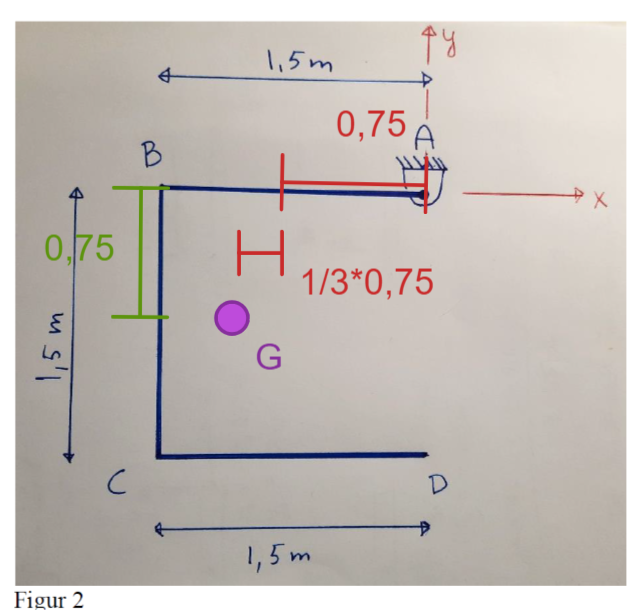

VI ser at de 3 stang elementer er ens

**x-retningen**

Her ligger AB og CD's centroider 0,75 m fra origo bidraget fra fra det sidste element bliver 1/3 af den totale masse og dermed "trækkes" tyngdepunktet 1/3 af den resterende længde ud af negativ x retning (0,75). 

x_G = -0.75 - 1/3 * 0.75

x_G = -1

y-retningen

her er vægten lille lidt fordelt fra B til C vi får der med centroiden i 0,75

y_G = -0.75

y_G = -0.7500

Vi får nu Tyngdepunktets position til punktet G (1; 0,75) markeret med lilla

**c)**

Det ses at der kun sker rotaion omkring z aksen

Masseinertimomentet om A findes ved at forskyde tyngdepunktet ind på enden af hver stang

BC forskydes længden L ind så den ligger på y-aksen

CD forskydes længden L op så den ligger på x-aksen

L = 1.5 %længden af hver stang

L = 1.5000

M = q * L

M = 3


d_BC = L %forskydelsen af BC's tyngde punkt 

d_BC = 1.5000


d_CD = L %forskydelsen af CD's tyngde punkt

d_CD = 1.5000


stangAB_I_zz = 1/3 * M * L^2 %ligger op af rotations aksen

stangAB_I_zz = 2.2500


stangBC_I_zz = 1/3 * M * L^2 + M*d_BC^2 % forskydes til rotations aksen

stangBC_I_zz = 9


stangCD_I_zz = 1/3 * M * L^2 + M*d_CD^2 % forskydes til rotations aksen

stangCD_I_zz = 9


disp('-----------------------------------------')

-----------------------------------------



%total inertimomentet er således
I_tot_zz = stangAB_I_zz + stangBC_I_zz + stangCD_I_zz

I_tot_zz = 20.2500

Således for vi et inertimoment på 


$$I = 20,25\ kg\ m^2$$


**d)**

**FBD**

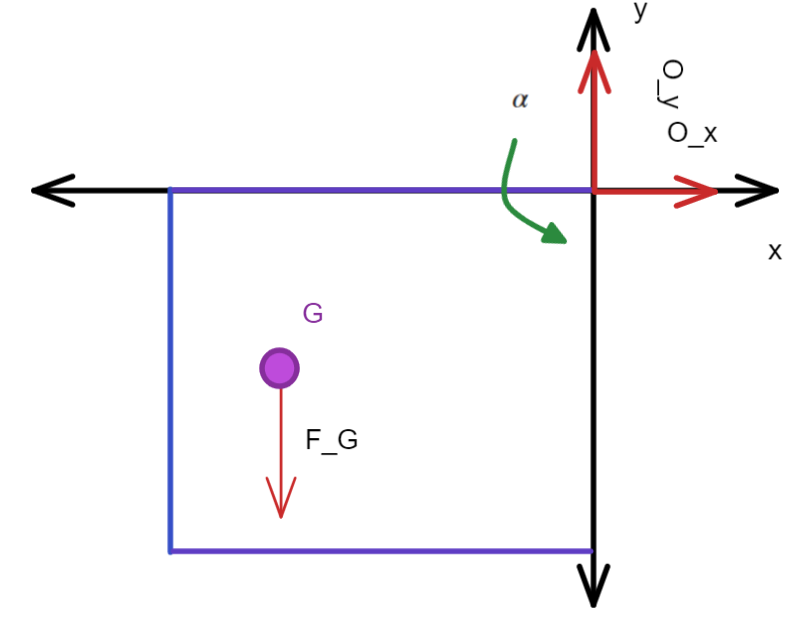

**KD**

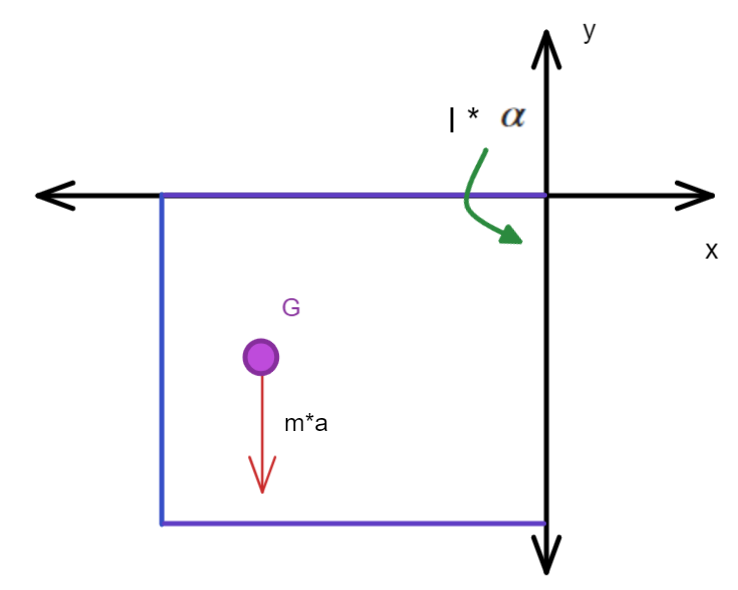

**e)**

**Vinkelaccelrationen finde med **$\alpha = a/r$

d = sqrt(y_G^2 + x_G^2)

d = 1.2500

theta = atand(y_G/x_G)

theta = 36.8699

a = g * sind(theta)

a = -5.8860

alpha = a / d

alpha = -4.7088

**f)**

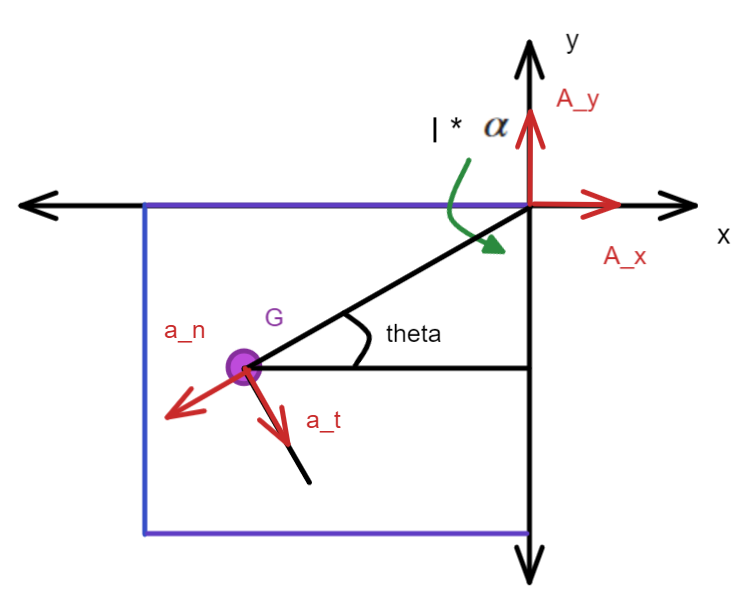


$$a_t = r \cdot \alpha$$



$$a_n = r \cdot \omega^2$$


a_t = d * alpha

a_t = -5.8860

omega = alpha * t

Unrecognized function or variable 't'.

a_n = d * omega

**g)**

A_x = a_n * cos(theta) + a_t * cos(theta)
A_y = a_n * sin(theta) + a_t * sin(theta)

## Opgave 3

Mathias Bruun Houmøller  -  202006837

a)

clear

